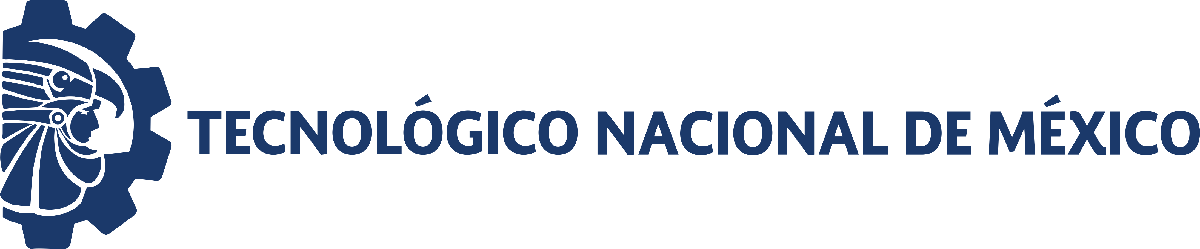                                 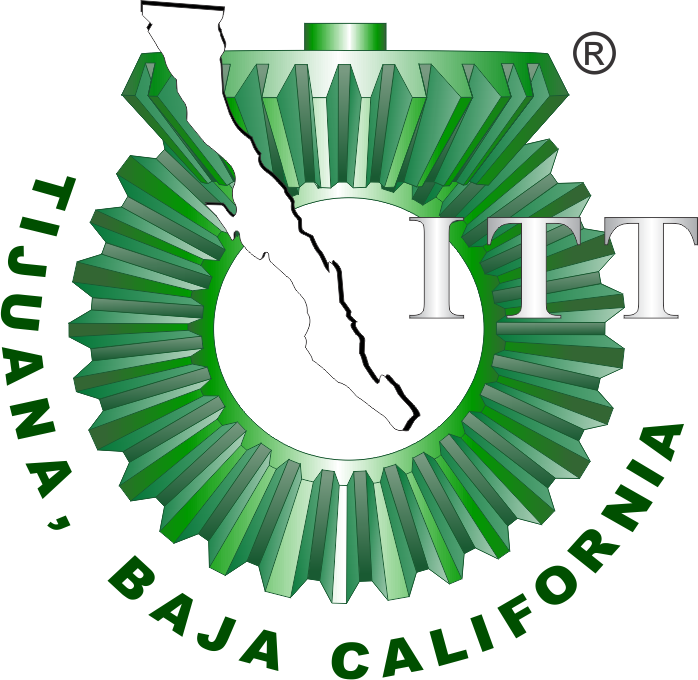

# Práctica tres: Modelado y control del sistema musculoesquelético

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

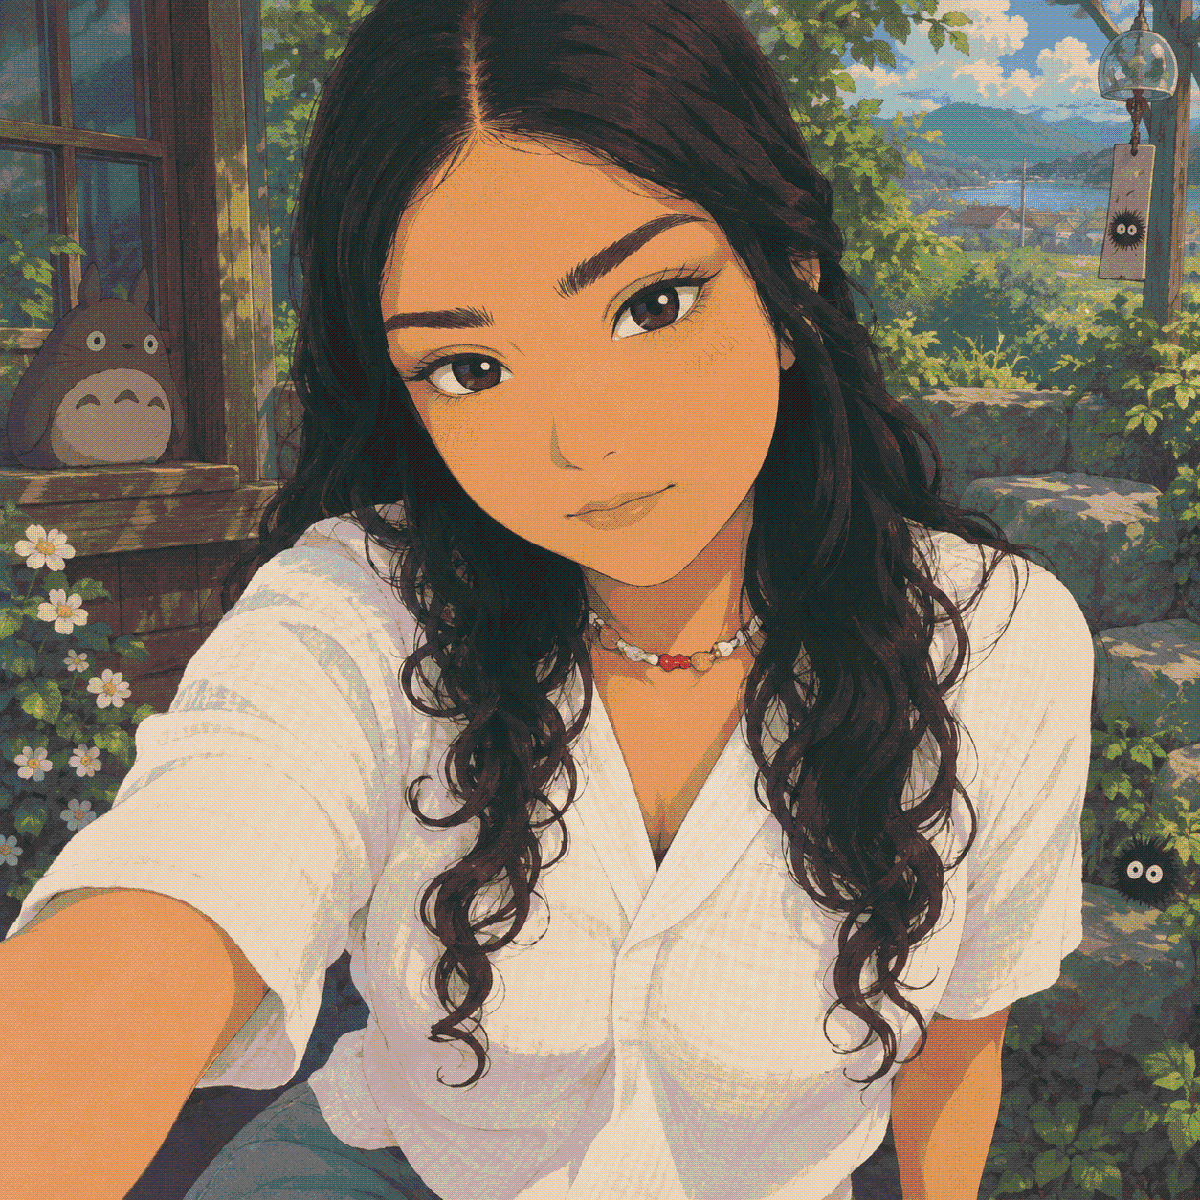

Nombre del alumno: **Zulema Guadalupe Tirado Manzo**

Número de control: **23210724**

Correo institucional: **l23210724@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')

open_system('sistema.slx')

parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
x = sim('sistema', parameters);

## **Respuesta al impulso unitario**

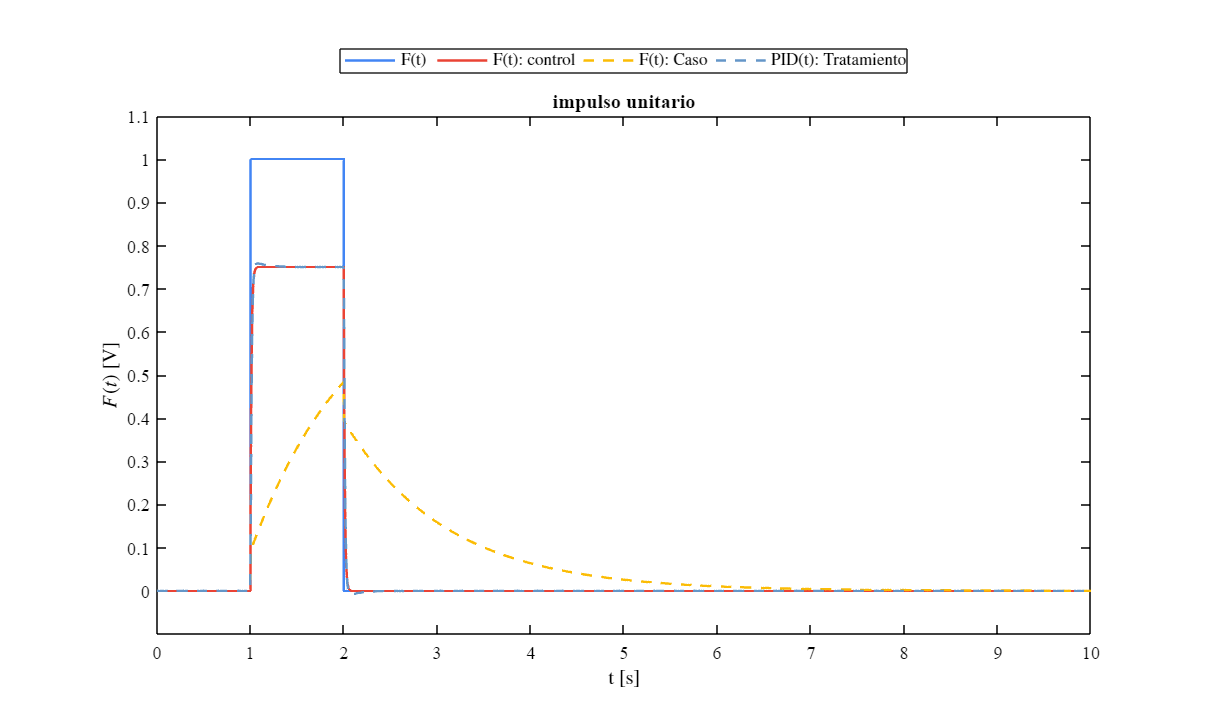

x = sim('sistema',parameters);
plotsignals(x.t,x.F,x.Fsx,x.Fsy,x.PID, 'impulso unitario')

## Modelo de EDOS

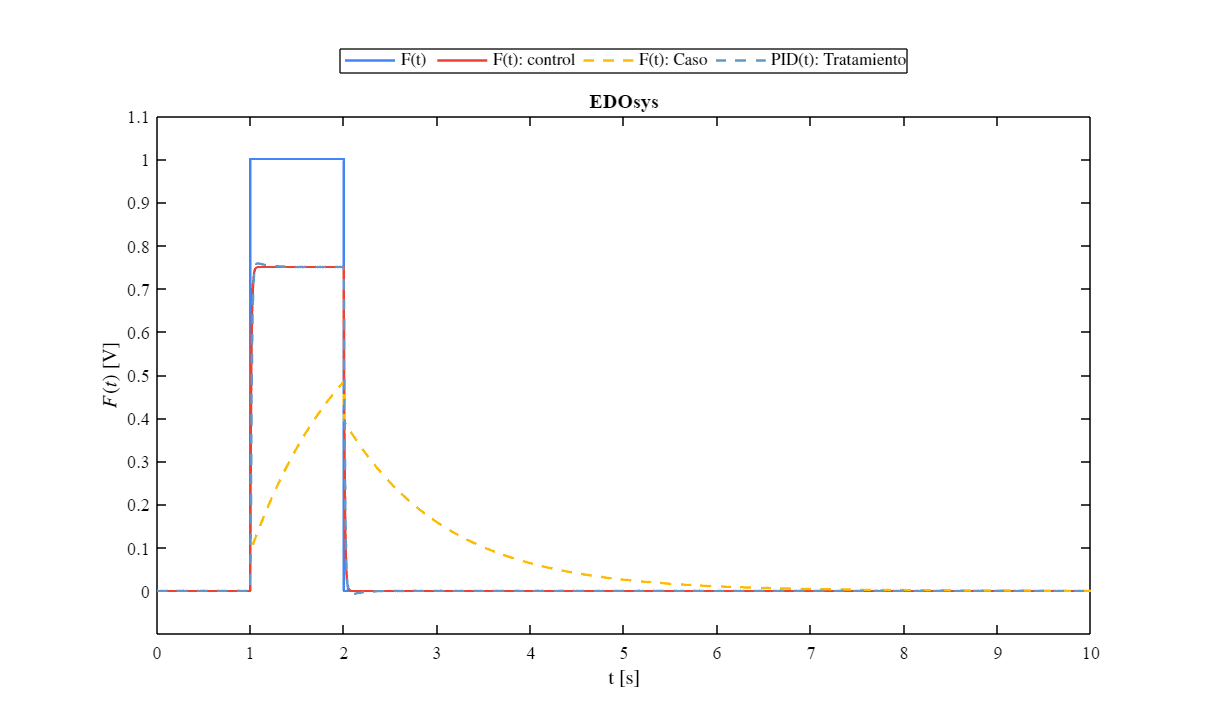

dt = 1e-3;
t = (0:dt:10)';
F = zeros(length(t),1); F(1/dt:2/dt) = 1;
PID = interp1(x.t, x.PID,t, 'previous');

par_control = [0.25, 10e-6,100e-6,100];
par_caso = [0.25,10e-6,100e-6,10e3];

Fs_control = musculoesqueletico(par_control, F, t);
Fs_caso = musculoesqueletico(par_caso, F, t);

plotsignals(t,F,Fs_control,Fs_caso,PID, 'EDOsys' )

function Fs = musculoesqueletico(par,F,t)
   alpha = par(1); Cs = par(2); Cp = par(3); R = par(4);
   t = t(:); F = F(:);
   n = length(t);
   x = zeros(n,1);
   for i = 1:n-1
       dt = t(i+1)-t(i);
       x(i+1) = x(i) + ((F(i)-x(i))/(R*(Cp+Cs)))*dt;
   end
   Fs = Cs*F/(Cp+Cs) + (1-alpha-Cs/(Cp+Cs))*x;
end


## Función: Respuestas de la simulación 

function plotsignals(t,F,Fsx,Fsy,PID,signal)
set(figure(),'color','w')
set(gcf,'units','inches','position', [0.5,0.5,12,7])
set(gca, 'fontname','times new roman','fontsize',11)
hold on; grid off; box on;
clr1 = [66, 133, 244]/255;
clr2 = [234, 67, 53]/255;
clr3 = [251, 188, 5]/255;
clr4 = [100,150,200]/255;
order = [clr1; clr2; clr3;clr4]; colororder(order)
xlabel('t [s]','Interpreter','latex')
ylabel('$F(t)$ [V]', 'Interpreter','latex')
xlim([0 10]); xticks(0:1:10)
ylim([-0.1 1.1]); yticks(0:0.1:1.1)
% Graficar tanto la simulación como el modelo de EDOs.
plot(t,F,'-',t,Fsx,'-',t,Fsy,'--',t,PID,'--','LineWidth',1.5,'MarkerSize',5,'MarkerIndices', 1:1e3:length(t));
L = legend('F(t)','F(t): control','F(t): Caso','PID(t): Tratamiento');
set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
title(signal,'Interpreter','none')
set(gcf,'Color','white')
set(gca,'Color','white','XColor','black','YColor','black')
set(L,'Color','white','TextColor','black')

exportgraphics(gcf,'_matlab.pdf','ContentType','vector')




end